serialportlist("available")'

ans = 8×1 string array
    "/dev/tty.RobsSoundLink"
    "/dev/cu.RobsSoundLink"
    "/dev/tty.BoseS1Pro"
    "/dev/cu.BoseS1Pro"
    "/dev/tty.Bluetooth-Incoming-Port"
    "/dev/cu.Bluetooth-Incoming-Port"
    "/dev/tty.usbmodem1301"
    "/dev/cu.usbmodem1301"


port = "/dev/tty.usbmodem1301";
if numel(evalin("base", "whos('robo')")) == 1
    clear robo;
end
robo = serialport(port, 115200)

robo =   Serialport with properties:

                 Port: "/dev/tty.usbmodem1301"
             BaudRate: 115200
    NumBytesAvailable: 0

  Show all properties, functions


configureTerminator(robo, "CR/LF");
flush(robo);
robo.UserData = struct("Data",[],"Count",1);
% configureCallback(robo,"terminator",@readSineWaveData);

Count is 8193
DONE! :)Count is 8193
DONE! :)

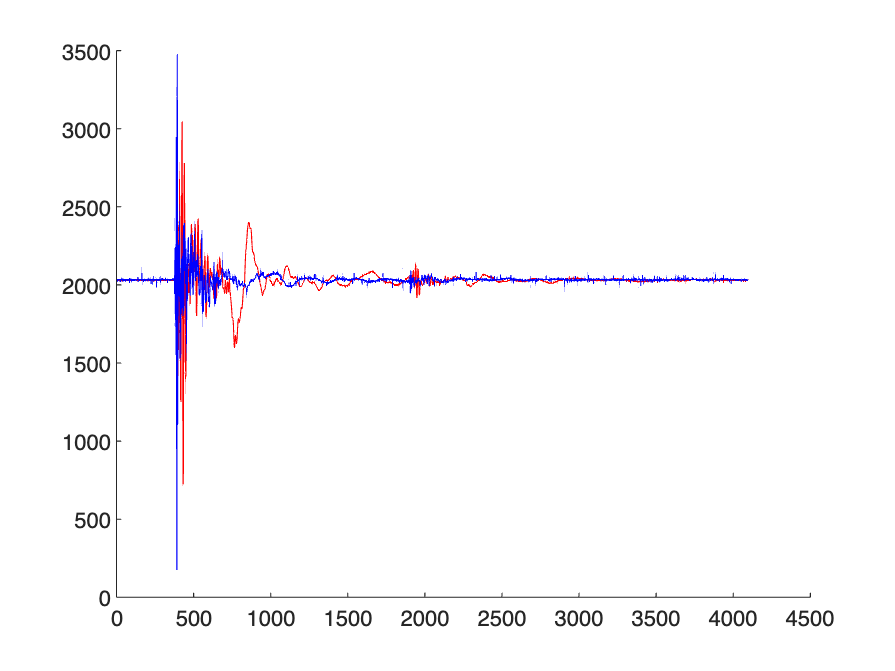

for c = 1:2
    robo.UserData = struct("Data",[],"Count",1, "Motion", 1);
    while (~strcmp(readline(robo), "DATA"))
    
    end
    while (readArduino(robo, "SOFTYRN"))
        
    end
end

function running = readArduino(src, type)
data = readline(src);
% fprintf("%s\n", data);

if strcmp(data, "DONE")
    fprintf("Count is %d\n", src.UserData.Count)
    data = src.UserData.Data;
    T = table(data(1:2:end)', data(2:2:end)');
    T.Properties.VariableNames = {'Piezo1', 'Piezo2'};
    s = type + "-" + string(datetime('now'), 'yyMMdd-HHmmss');
    writetable(T, "data/" + s + ".csv");
    fprintf("DONE! :)")
    clf;
    hold on;
    plot(T.Piezo1, Color='r');
    plot(T.Piezo2, Color='b');
    running = false;
    return;
else
    src.UserData.Data(end+1) = str2double(data);
    src.UserData.Count = src.UserData.Count + 1;
end
running = true;
end